### Probe-Drogue Capture Geometry

% ASSUMPTIONS / INPUTS TO VERIFY

clear; clc; close all;

% Requirements
radial_offset  = 0.10;          % m, SYS.07
angular_offset = deg2rad(4);    % rad, SYS.08
pos_error = 0.005;              % m, setup position error from GNC/OptiTrack (VERIFY)
design_margin = 0.010;          % m, extra radial margin on the mouth

% ABV (same as achievability_analysis.mlx)
ft2m = 0.3048;
abv_width = 1.125 * ft2m;       % m
r_mech_mount = 0.5625 * ft2m;   % m, mechanism base ahead of ABV center (VERIFY)

% Probe (DRAWING VALUES -- VERIFY)
L_ext   = 0.000;    % m, offsets defined at the drogue mouth plane (drogue is on the ABV)
r_tip   = 0.0143;   % m, probe front-face radius (Mk3.5 CAD)
r_shaft = 0.012;                % m, shaft radius where it enters the socket

% Drogue (DRAWING VALUES -- VERIFY)
R_mouth = 0.119;    % m, Mk4 with skirt for 0.10 m capture (Mk3.5 = 0.055)
theta_c   = deg2rad(45);        % rad, skirt half-angle (Mk3.5 lead-in = 30 deg)
R_throat  = 0.014;              % m, socket (bore) radius at the bottom of the cone
L_socket  = 0.030;              % m, socket engagement depth
L_cone_max = 0.150;             % m, max cone length that fits the envelope

% Friction, probe material (rows) x drogue material (cols): Al, Delrin, PETG
mat_name = {'Al 6061-T6', 'Delrin', 'PETG'};
mu = [0.60 0.20 0.35;
      0.20 0.25 0.30;
      0.35 0.30 0.45];
probe_mat = 3; drogue_mat = 3;  % candidate pairing (index into mat_name)

### 1) Entry: required mouth size

e_radial   = radial_offset + pos_error;                                  % m, tip offset, radial test
e_angular  = L_ext*sin(angular_offset) + pos_error;                      % m, tip offset, angular test
e_combined = radial_offset + L_ext*sin(angular_offset) + pos_error;      % m, both at once
R_req_tests    = max(e_radial, e_angular) + r_tip + design_margin;       % m
R_req_combined = e_combined + r_tip + design_margin;                     % m

fprintf('\n 1) ENTRY \n');


 1) ENTRY 


fprintf('Tip lateral offset: radial test %.1f mm, angular test %.1f mm, combined %.1f mm\n', ...
    e_radial*1e3, e_angular*1e3, e_combined*1e3);

Tip lateral offset: radial test 105.0 mm, angular test 10.6 mm, combined 110.6 mm


fprintf('Required mouth radius: %.1f mm (one offset per test), %.1f mm (combined)\n', ...
    R_req_tests*1e3, R_req_combined*1e3);

Required mouth radius: 125.0 mm (one offset per test), 130.6 mm (combined)


fprintf('  -> mouth diameter %.0f-%.0f mm = %.0f-%.0f%% of the %.0f mm ABV width\n', ...
    2*R_req_tests*1e3, 2*R_req_combined*1e3, 100*2*R_req_tests/abv_width, 100*2*R_req_combined/abv_width, abv_width*1e3);

  -> mouth diameter 250-261 mm = 73-76% of the 343 mm ABV width


if R_mouth >= R_req_combined
    fprintf('Design R_mouth = %.1f mm: PASSES the combined case\n', R_mouth*1e3);
elseif R_mouth >= R_req_tests
    fprintf('Design R_mouth = %.1f mm: passes separate tests, FAILS combined\n', R_mouth*1e3);
else
    fprintf('Design R_mouth = %.1f mm: FAILS -- the radial test misses the drogue\n', R_mouth*1e3);
end

Design R_mouth = 135.0 mm: PASSES the combined case


### 2) Sliding: maximum cone half-angle per material pair

phi = atan(mu);                                        % rad, friction angle
theta_max = pi/2 - phi - angular_offset;               % rad, at full yaw offset
fprintf('\n 2) SLIDING: max cone half-angle (deg) at %.0f deg yaw, probe (rows) x drogue (cols)\n', rad2deg(angular_offset));


 2) SLIDING: max cone half-angle (deg) at 4 deg yaw, probe (rows) x drogue (cols)


fprintf('%-12s', '');

for d = 1:3, fprintf(' %11s', mat_name{d}); end

  Al 6061-T6      Delrin        PETG

fprintf('\n');
for p = 1:3
    fprintf('%-12s', mat_name{p});
    for d = 1:3, fprintf(' %11.1f', rad2deg(theta_max(p,d))); end
    fprintf('\n');
end

Al 6061-T6  

        55.0        74.7        66.7

Delrin      

        74.7        72.0        69.3

PETG        

        66.7        69.3        61.8

th_lim = theta_max(probe_mat, drogue_mat);
fprintf('Candidate %s probe on %s drogue: limit %.1f deg, design %.1f deg -> ', ...
    mat_name{probe_mat}, mat_name{drogue_mat}, rad2deg(th_lim), rad2deg(theta_c));

Candidate PETG probe on PETG drogue: limit 61.8 deg, design 45.0 deg -> 

if theta_c <= th_lim, fprintf('PASS (%.1f deg margin)\n', rad2deg(th_lim - theta_c));
else, fprintf('FAIL: tip will stick on the wall\n'); end

PASS (16.8 deg margin)


### 3) Cone length

L_cone_design = (R_mouth - R_throat) / tan(theta_c);
L_cone_req    = (R_req_combined - R_throat) / tan(theta_c);   % at design angle, required mouth
th_min_len    = atan((R_req_combined - R_throat) / L_cone_max); % shallowest angle that fits
fprintf('\n 3) CONE LENGTH \n');


 3) CONE LENGTH 


fprintf('Design cone length: %.1f mm. With the required mouth at %.0f deg: %.1f mm (limit %.0f mm)\n', ...
    L_cone_design*1e3, rad2deg(theta_c), L_cone_req*1e3, L_cone_max*1e3);

Design cone length: 121.0 mm. With the required mouth at 45 deg: 116.6 mm (limit 150 mm)


fprintf('To fit %.0f mm, the half-angle must be at least %.1f deg\n', L_cone_max*1e3, rad2deg(th_min_len));

To fit 150 mm, the half-angle must be at least 37.9 deg


fprintf('Usable half-angle window for %s on %s: %.1f to %.1f deg\n', mat_name{probe_mat}, ...
    mat_name{drogue_mat}, rad2deg(th_min_len), rad2deg(th_lim));

Usable half-angle window for PETG on PETG: 37.9 to 61.8 deg


if th_min_len > th_lim
    fprintf('  NO WINDOW: lower friction, longer envelope, or smaller offset needed\n');
end

### 4) Socket entry and self-alignment

c_rad = R_throat - r_shaft;                         % m, radial clearance
psi_socket = 2*c_rad / L_socket;                    % rad, max misalignment (small angle)
c_req = angular_offset * L_socket / 2;              % m, clearance for full 4 deg
L_cg_tip = r_mech_mount + L_ext;                    % m, ABV center to probe tip

fprintf('\n 4) SOCKET ENTRY \n');


 4) SOCKET ENTRY 


fprintf('Radial clearance %.2f mm over %.0f mm depth accepts %.2f deg of misalignment\n', ...
    c_rad*1e3, L_socket*1e3, rad2deg(psi_socket));

Radial clearance 2.00 mm over 30 mm depth accepts 7.64 deg of misalignment


fprintf('Accepting the full %.0f deg without rotating needs %.2f mm radial clearance\n', ...
    rad2deg(angular_offset), c_req*1e3);

Accepting the full 4 deg without rotating needs 1.05 mm radial clearance


fprintf('Probe tip is %.0f mm ahead of the ABV center: wall contact turns the nose\n', L_cg_tip*1e3);

Probe tip is 251 mm ahead of the ABV center: wall contact turns the nose


fprintf('toward the axis, so the cone REDUCES the yaw error before the socket.\n');

toward the axis, so the cone REDUCES the yaw error before the socket.


fprintf('If clearance is below %.2f mm, add a chamfer or lead-in on the socket so\n', c_req*1e3);

If clearance is below 1.05 mm, add a chamfer or lead-in on the socket so


fprintf('the remaining yaw is taken out by the cone, not by wedging in the bore.\n');

the remaining yaw is taken out by the cone, not by wedging in the bore.


### Capture envelope

Shaded region: offset combinations the current drawing values capture (entry + sliding, candidate material pair). The markers are the SYS.07 and SYS.08 test points.

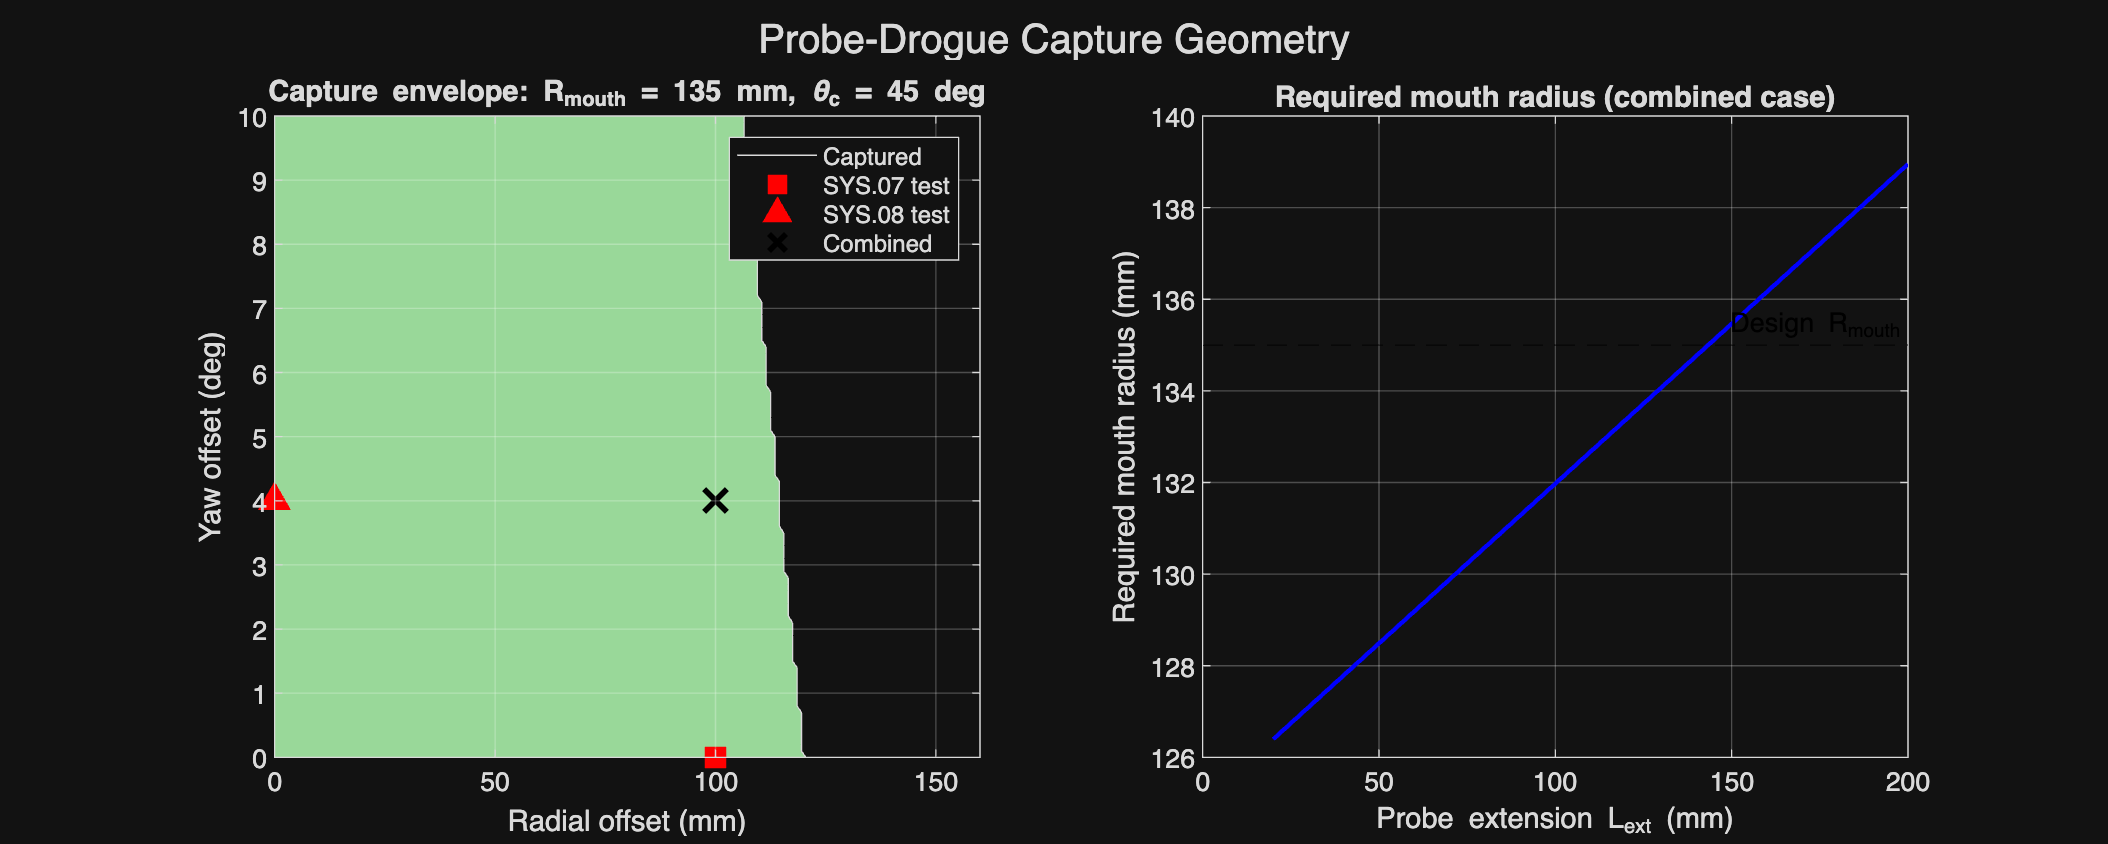

dr_grid  = linspace(0, 0.16, 161);              % m
psi_grid = deg2rad(linspace(0, 10, 101));       % rad
[DR, PSI] = meshgrid(dr_grid, psi_grid);
entry_ok = (DR + L_ext*sin(PSI) + pos_error + r_tip) <= R_mouth;
slide_ok = theta_c <= (pi/2 - phi(probe_mat, drogue_mat) - PSI);
cap = entry_ok & slide_ok;

L_ext_sweep = linspace(0.02, 0.20, 40);
R_req_sweep = radial_offset + L_ext_sweep*sin(angular_offset) + pos_error + r_tip + design_margin;

figure('Name', 'Capture Geometry', 'Position', [100 100 1100 440]);
subplot(1,2,1);
contourf(DR*1e3, rad2deg(PSI), double(cap), [0.5 0.5]); colormap([1 1 1; 0.6 0.85 0.6]); hold on;
plot(radial_offset*1e3, 0, 'rs', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(0, rad2deg(angular_offset), 'r^', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(radial_offset*1e3, rad2deg(angular_offset), 'kx', 'MarkerSize', 12, 'LineWidth', 2);
xlabel('Radial offset (mm)'); ylabel('Yaw offset (deg)');
title(sprintf('Capture envelope: R_{mouth} = %.0f mm, \\theta_c = %.0f deg', R_mouth*1e3, rad2deg(theta_c)));
legend('Captured', 'SYS.07 test', 'SYS.08 test', 'Combined', 'Location', 'northeast'); grid on;

subplot(1,2,2);
plot(L_ext_sweep*1e3, R_req_sweep*1e3, 'b-', 'LineWidth', 1.6); hold on;
yline(R_mouth*1e3, 'k--', 'Design R_{mouth}');
xlabel('Probe extension L_{ext} (mm)'); ylabel('Required mouth radius (mm)');
title('Required mouth radius (combined case)'); grid on;

sgtitle('Probe-Drogue Capture Geometry');